# Numerical Calculus (3/4)

-----

# 3. The differential equation

## 3.1 The differential equation

Two ways to think about a differential equation. One is as a relationship between derivatives of u(t) and the function itself. 

- A population of E. coli in a large petri dish: $du/dt = 5u$

- A charged biomolecule flying through a mass spectrometer: $m\cdot d^2u/dt^2 = -\zeta \cdot du/dt + q \cdot E_0$

Any function u(t) either satisfies the differential equation, or doesn't. Sometimes it is hard to guess the solution.

- 
$$u(t) = 27.3 \exp(5t) .....u(t) = 1000 \exp(5t) .....u(t) = 12 \exp(-3t)$$


- 
$$u(t) = (1-\exp(-\zeta\cdot t/m)) \cdot (q E_0/m)t$$


One differential equation often has many solutions. 

A differential equation involving a function of one variable, e.g., time t, is called an *ordinary differential equation (ODE)*.

## 3.2 The set of models du/dt = f(u), u(0)=u_0

The second way of thinking about a differential equation is as a rule that tells you, given the state of a system at time t, how it is going to change.

In this case, for the model to make a prediction, we need to state an initial condition.

A gene produces protein at a constant rate a (copies per hour). The proteins are removed at a per-molecule rate b (1/hrs).

% dP/dt = a - b*P

If the protein promotes its own expression, then one model of this is:

% dP/dt = (a_0 + a_1*P) - b*P

If the protein promotes its own degradation, then one model of this is:

% dP/dt = a - (b_0 + b_1*P)*P

Question: Why did the modeller choose to put an asymmetry between production (constant) and removal (linear)?

## 3.3 Numerical ODEs

## 3.3.1 Euler method and more complicated methods

Thinking about an ODE as a rule that states how a system will change, there is an obvious way to simulate numerical solutions: Pick a small dt, and simulate just like for a discrete-time system. This is called *Forward Euler Method*. 

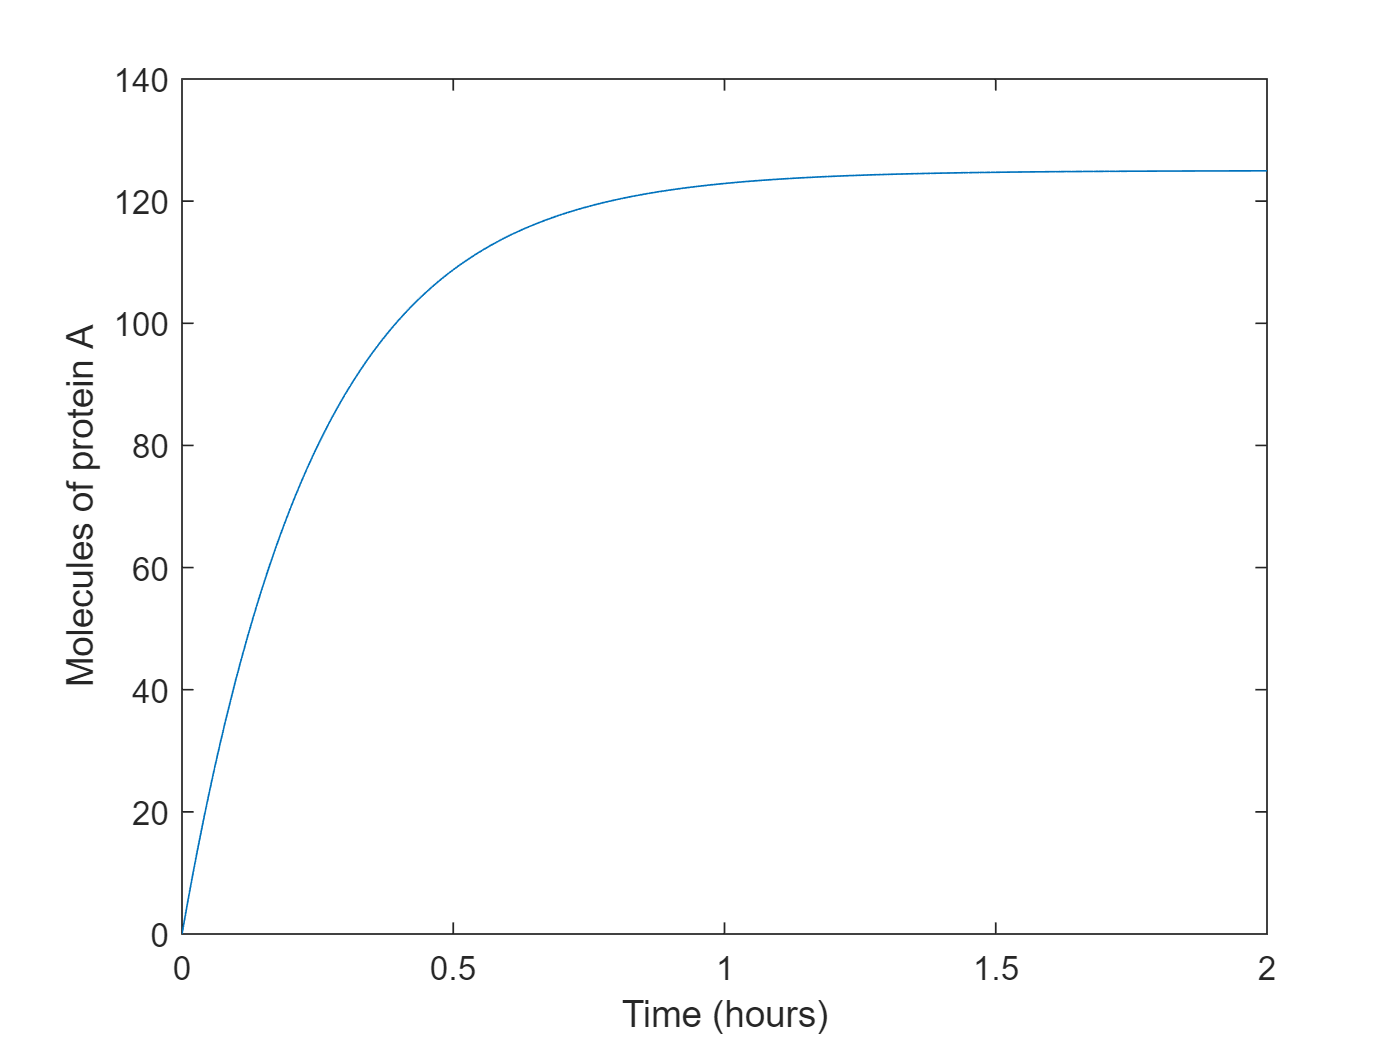


dt = 0.01; % time step

a_0 = 500; % molecules per hour
a_1 = 0; % molecules per hour, per existing molecule of A
b = 4; % 1/hrs

ntMax = 2e2;

P = zeros(1,ntMax);
tArray = 0:dt:(ntMax*dt);

P(1) = 0; % initial condition

for nt=1:ntMax
    
    dPdt = (a_0 + a_1*P(nt)) - b*P(nt); % "dPdt" is a convenient short-hand for "dP/dt"
    
    P(nt+1) = P(nt) + dPdt*dt;
    
end % finished loop through time


% plot it
figure
plot(tArray, P);
ylabel('Molecules of protein A');
xlabel('Time (hours)');

## 3.3.1.1 Solving an ODE system with ode45

Matlab has built-in ODE solvers that are very good. These use more sophisticated methods that choose their own timestep dt. 

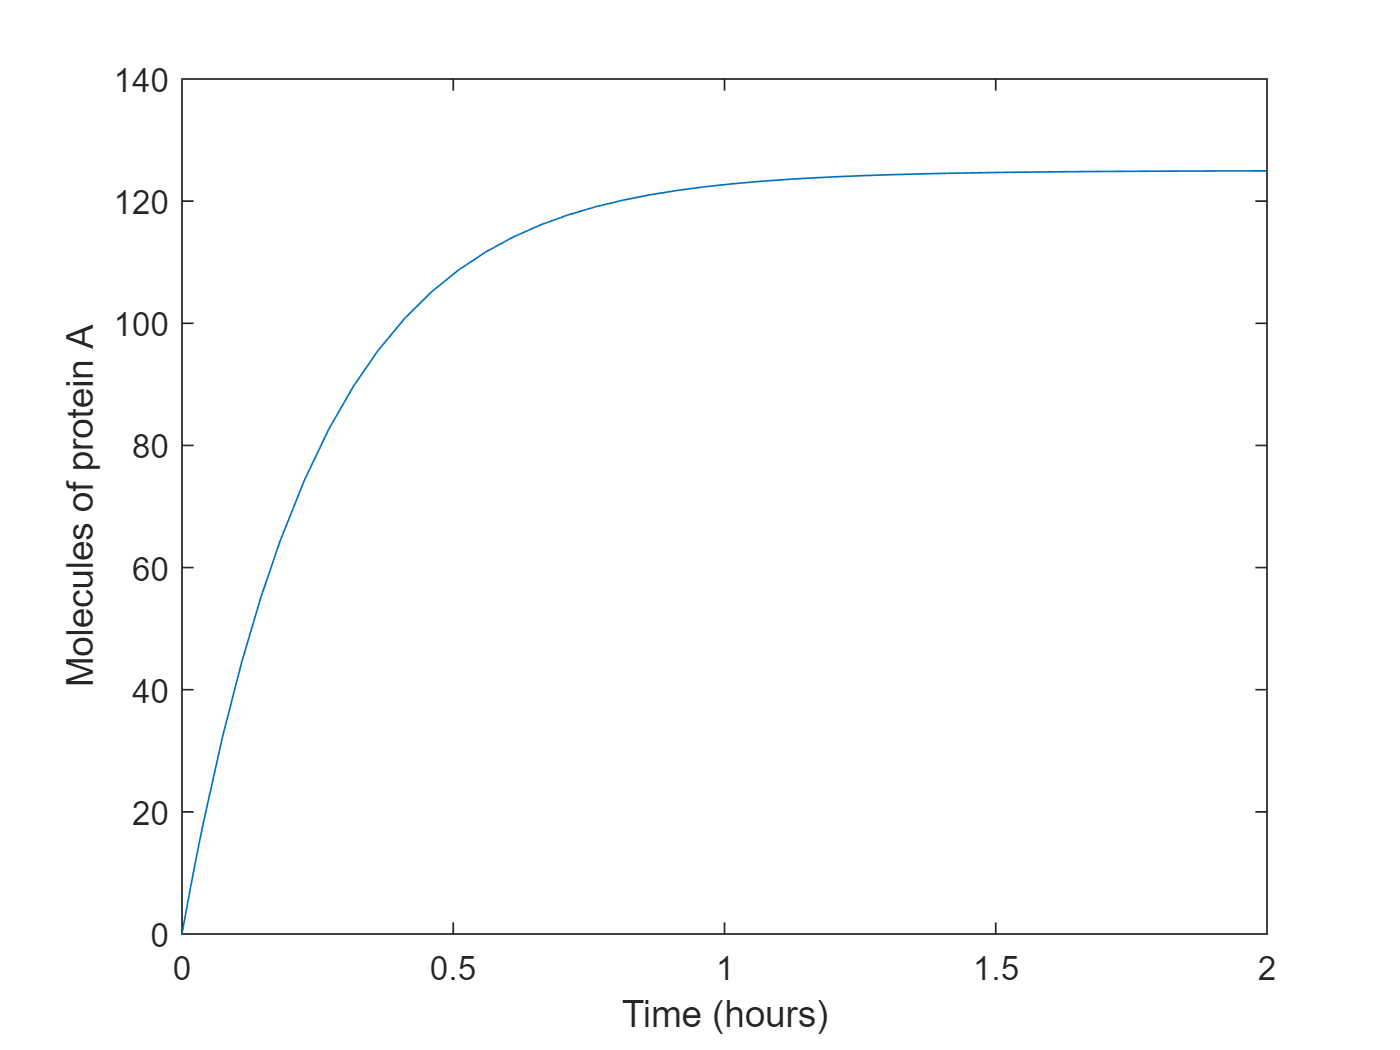

dPdt =@(P) (a_0 + a_1*P) - b*P; % Define the ODE 

[T, P] = ode45( @(t,x)dPdt(x), [0,2.0], 0); % Matlab's built-in ODE solver, ode45

plot(T,P)
ylabel('Molecules of protein A');
xlabel('Time (hours)');

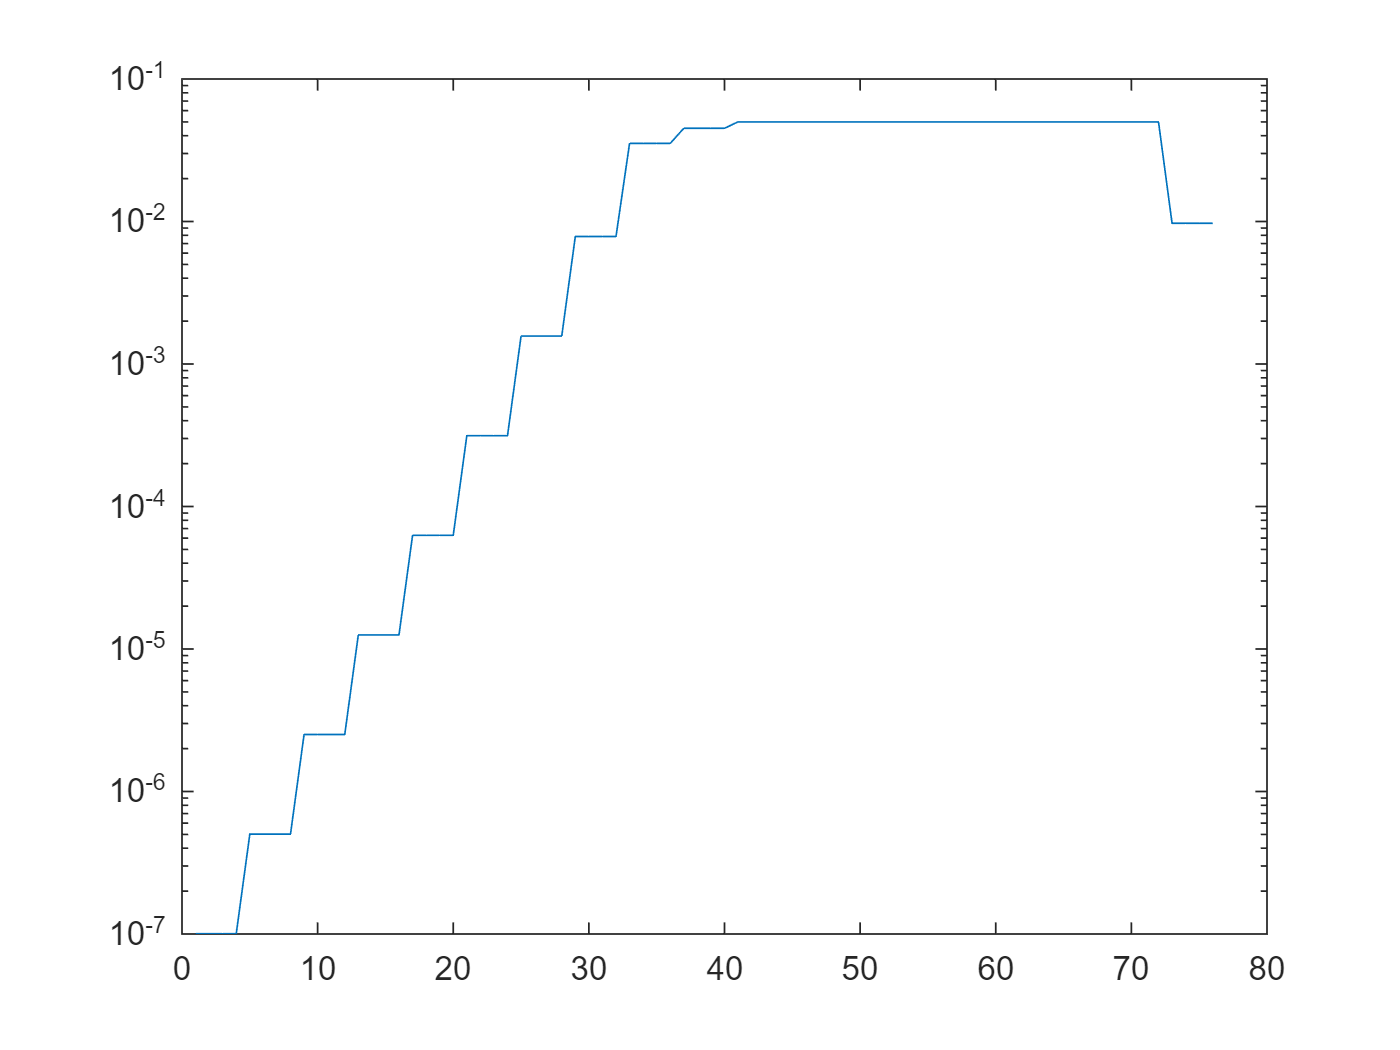

% how big are the timesteps chosen by ode45()? 
% (axis labels for something quick like this?)
plot(diff(T));set(gca,'yscale','log')

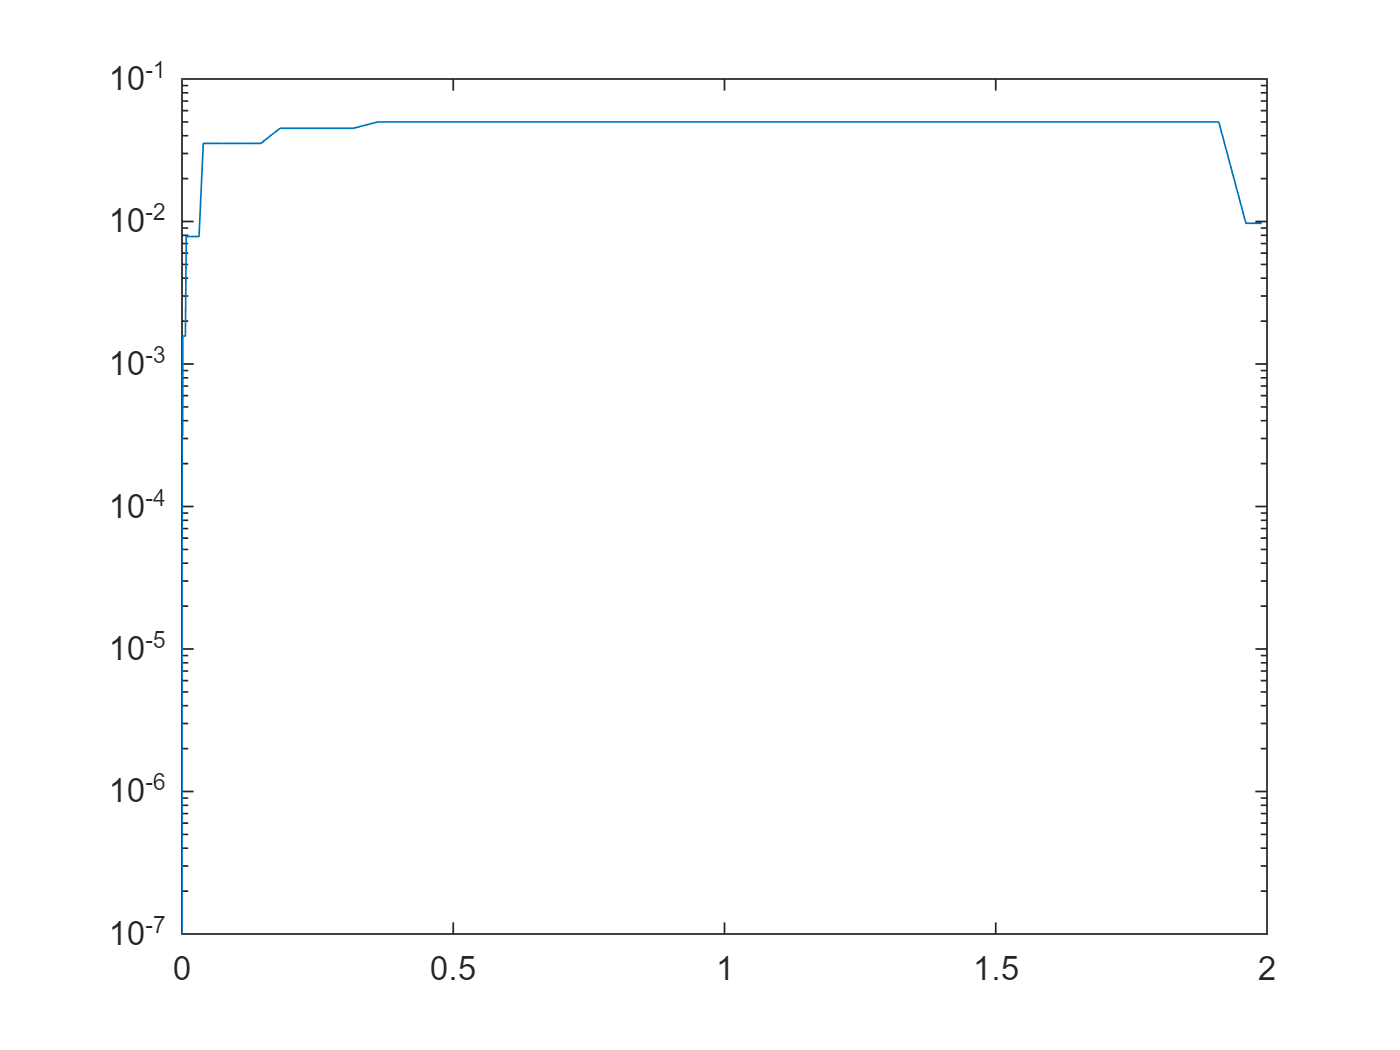

plot(T(1:end-1),diff(T));set(gca,'yscale','log')

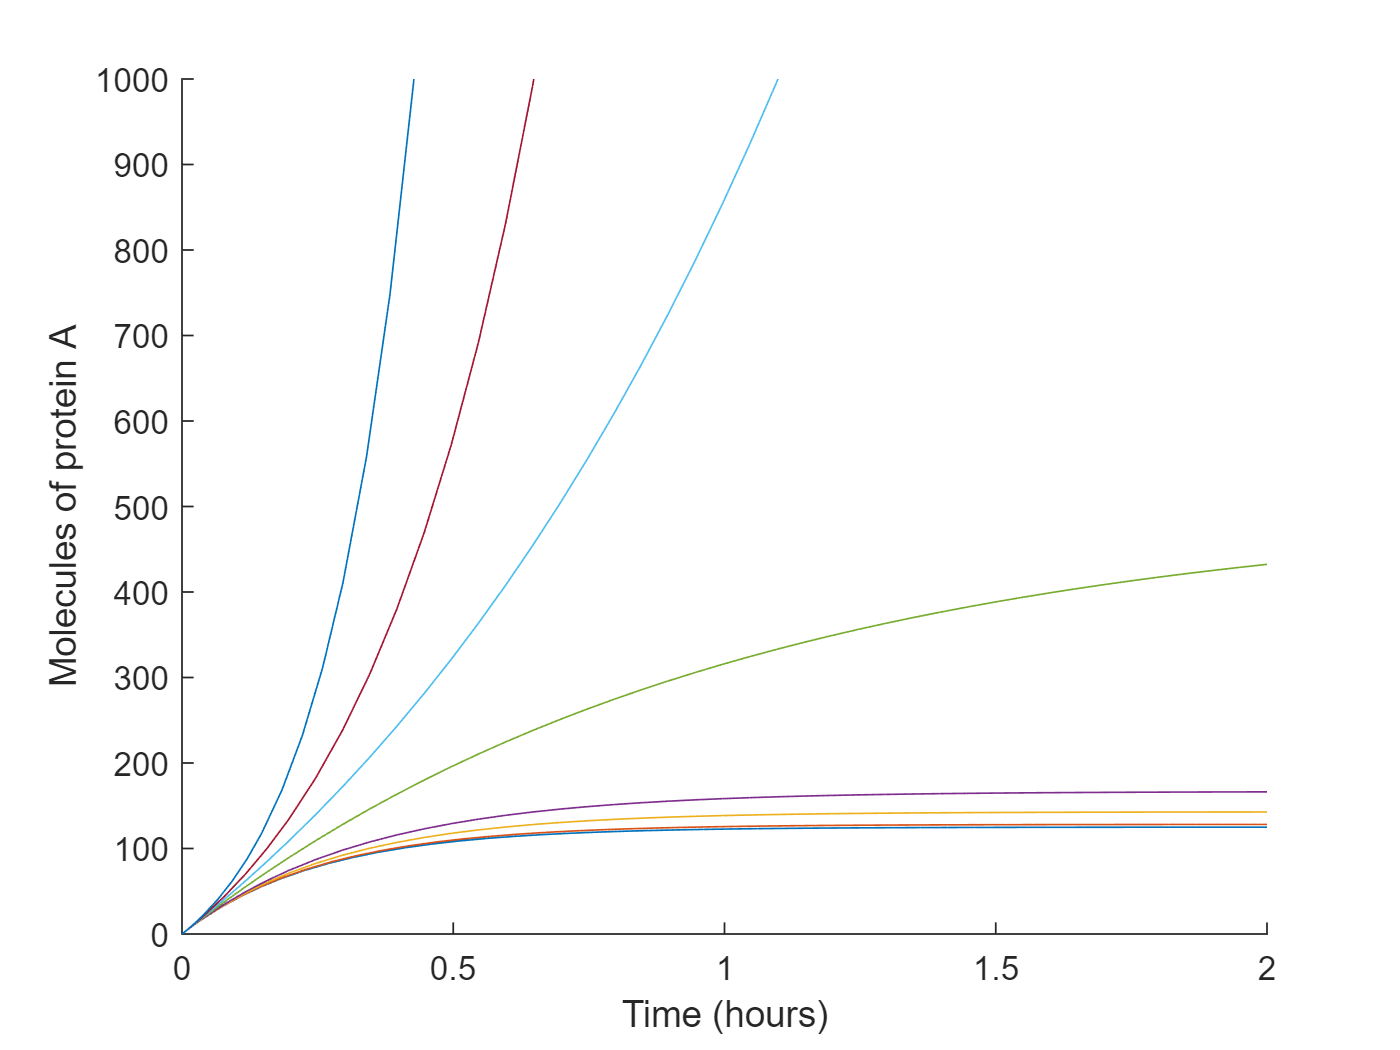

% Let's explore the solution for different values of a_1

figure;
hold on;
for a_1 = [0 0.1 0.5 1 3 5 7 10]
    
    dPdt =@(P) (a_0 + a_1*P) - b*P; % Why do we need to redefine the ODE in the loop? *****************
    
    [T, P] = ode45(@(t,x)dPdt(x), [0,2.0], 0);
    
    plot(T,P);
end
set(gca,'ylim', [0,1000])
ylabel('Molecules of protein A');
xlabel('Time (hours)');

## 3.4 Analytical examples

Linear ODEs that look like 


$$du/dt = a+b\cdot u$$


All of the solutions are $C_1 + C_2 \exp(b\cdot t)$. If $b>0$, exponential growth. If $b<0$, exponential decay.


$$dx/dt = x^2, x(0) = 0.2$$


Solution: $x(t) = 1/(5-t)$

gives finite time blow-up

[T, X] = ode45(@(t,x)x^2, [0,6.0], 0.2);

## 3.5 Mini exercise: Steady states via Symbolic, graphical (phase line), numerical (fzero), and ode solver

What value does an ODE model go to steady state? When du/dt=0!

Gene expression with some positive feedback in expression:

dPdt =@(P) (a_0 + a_1*P) - b*P;

a_1 = 0.5

Plot dPdt versus P. (Note this is different from dPdt versus t)

What value does this predict a steady state protein level? 

Find the steady state using 2 alternative approaches:

- Use symbolic math (and paper and pencil) to find the steady state.

- Use ode45 to numerically find the steady state.

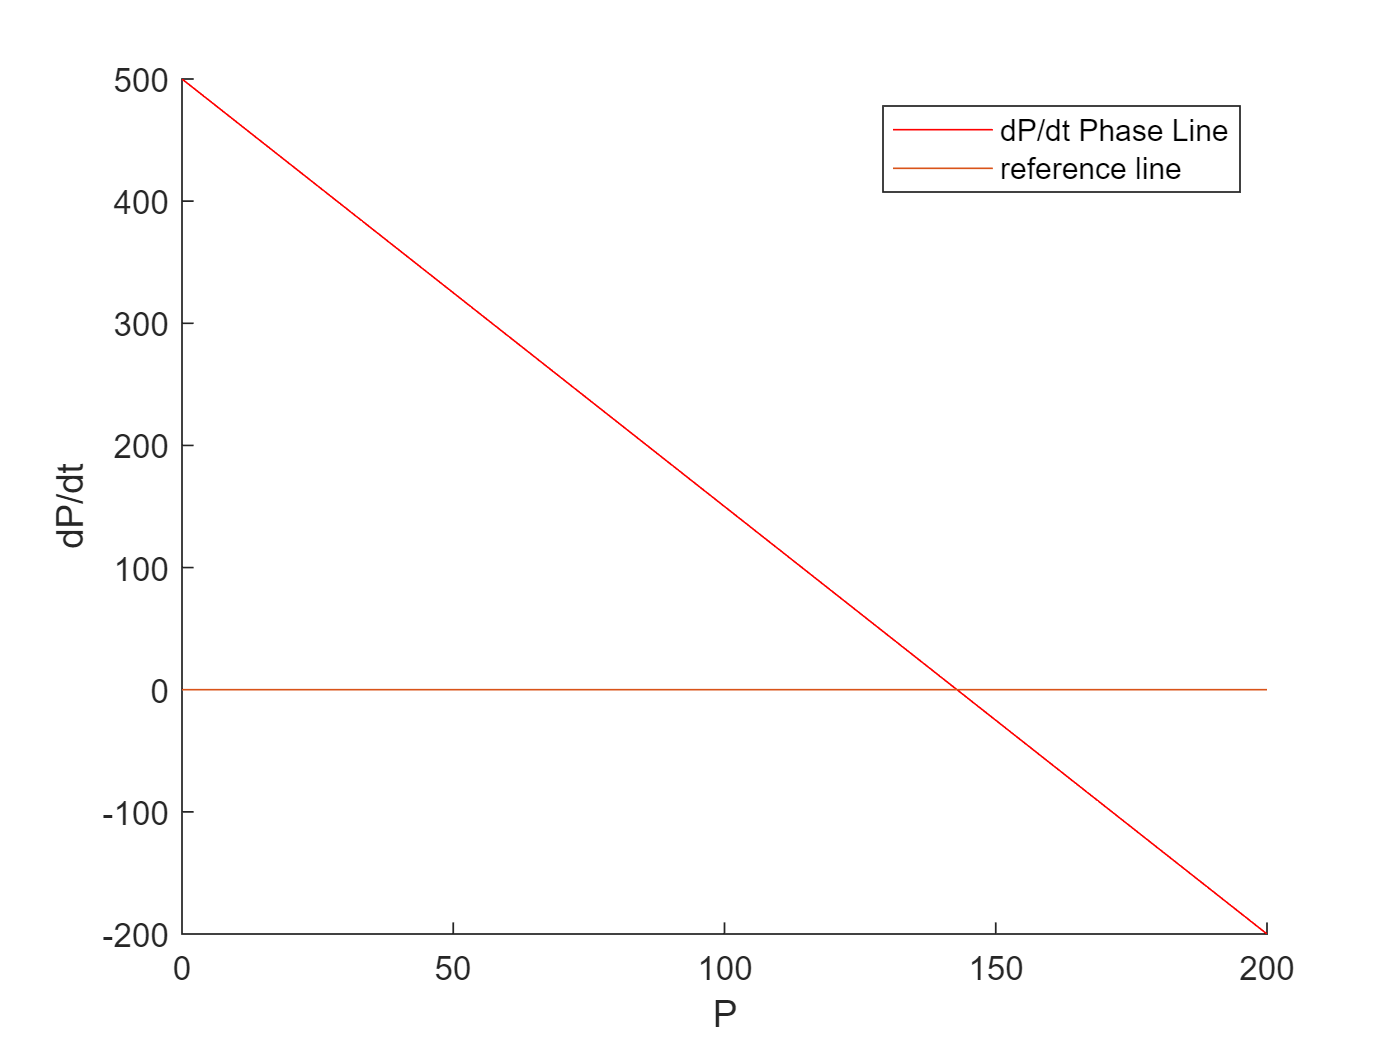

% define ODE and parameters
a_0 = 500; % molecules per hour
a_1 = 0.5; % molecules per hour, per existing molecule of A
b = 4; % 1/hrs
dPdt =@(P) (a_0 + a_1*P) - b*P;

% Find the steady state by plotting the dP/dt versus P
PArray = linspace(0,200,200);
dPdtPhaseLine = dPdt(PArray);
figure; hold on;
plot(PArray,dPdtPhaseLine,'r');
ylabel('dP/dt');
xlabel('P');
plot([0,200],[0,0]); % horizontal line at dPdt=0
legend('dP/dt Phase Line','reference line');
% Find the steady state symbolically ("pencil and paper")
pSteady = a_0 / (b-a_1);

text = ['The symbolic steady state is ', num2str(pSteady,7)];
disp(text)
% Find the steady state by simulating the ODE
[T_sol, X_sol] = ode45(@(t,x)dPdt(x), [0,6.0], 0);

The symbolic steady state is 142.8571


display(X_sol(end))

  142.8571

